=================================================================================

# Práctica 1 - Algoritmos

## Aprendemos...

## 1. Introducción a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

 [A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

#### **Ejercicio 1. Calcula las siguientes cantidades**

$r= \sqrt{1-\frac{2}{\pi^5}}$; $r = e^2 \ln 5$; $r = \sin^2 2 + \cos^2 4$

format long

e = exp(1)

e =    2.718281828459045



r1 = sqrt(1 - (2 / (pi^5)))

r1 =    0.996726879698693


r2 = e^2*log(5)

r2 =   11.892227022721402


r3 = sin(2)^2 + cos(4)^2

r3 =    1.254071793527499


#### **Ejercicio 2. Gráficas**

Haz una gráfica por las siguientes funciones:

Toma un mínimo de 50 puntos en el intervalo; representa las gráficas con título y cuadrícula.

1. $f(x) = x^5e^{-x^2}-\frac{\sin x}{x^2 + 1}$ para $x\in [-2\pi, 2\pi]$

x = linspace(-2*pi, 2*pi, 50)

x =   -6.283185307179586  -6.026728764029398  -5.770272220879211  -5.513815677729024  -5.257359134578837  -5.000902591428650  -4.744446048278463  -4.487989505128276  -4.231532961978089  -3.975076418827901  -3.718619875677714  -3.462163332527527  -3.205706789377340  -2.949250246227153  -2.692793703076966  -2.436337159926778  -2.179880616776591  -1.923424073626404  -1.666967530476217  -1.410510987326030  -1.154054444175842  -0.897597901025655  -0.641141357875468  -0.384684814725281  -0.128228271575094   0.128228271575094   0.384684814725281   0.641141357875468   0.897597901025655   1.154054444175842   1.410510987326030   1.666967530476217   1.923424073626404   2.179880616776591   2.436337159926778   2.692793703076966   2.949250246227153   3.205706789377340   3.462163332527527   3.718619875677714   3.975076418827901   4.231532961978089   4.487989505128276   4.744446048278463   5.000902591428650   5.257359134578837   5.513815677729024   5.770272220879211   6.026728764029398   6.28318530717

y = (x.^5) .* exp(-x .^2) - (sin(x) ./ (x.^2 + 1))

y =   -0.000000000000070  -0.006796480810525  -0.014308285483049  -0.022153969245827  -0.029858523050965  -0.036859086757873  -0.042514059360858  -0.046116472102001  -0.046918150510466  -0.044197184832122  -0.037492674920093  -0.027361815919931  -0.017338198498195  -0.017530869351917  -0.047850548774487  -0.133434738666399  -0.282466256693181  -0.451450622117462  -0.536102120725012  -0.433334866447211  -0.148263988529469   0.172665020563601   0.352052288027471   0.319627282361949   0.125774453950719  -0.125774453950719  -0.319627282361949  -0.352052288027471  -0.172665020563601   0.148263988529469   0.433334866447211   0.536102120725012   0.451450622117462   0.282466256693181   0.133434738666399   0.047850548774487   0.017530869351917   0.017338198498195   0.027361815919931   0.037492674920093   0.044197184832122   0.046918150510466   0.046116472102001   0.042514059360858   0.036859086757873   0.029858523050965   0.022153969245827   0.014308285483049   0.006796480810525   0.00000000000

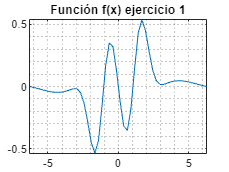


plot(x,y)
title("Función f(x) ejercicio 1")
grid minor

2. $f(x)= \frac{x^2 -4x-7}{x^2-x-6}$ para $-6\le x\le 6$ (presenta dos asíntotas)

x = linspace(-6,6,50)

x =   -6.000000000000000  -5.755102040816326  -5.510204081632653  -5.265306122448980  -5.020408163265306  -4.775510204081632  -4.530612244897959  -4.285714285714286  -4.040816326530612  -3.795918367346939  -3.551020408163265  -3.306122448979592  -3.061224489795918  -2.816326530612245  -2.571428571428571  -2.326530612244898  -2.081632653061225  -1.836734693877551  -1.591836734693878  -1.346938775510204  -1.102040816326531  -0.857142857142857  -0.612244897959184  -0.367346938775510  -0.122448979591837   0.122448979591837   0.367346938775510   0.612244897959184   0.857142857142857   1.102040816326531   1.346938775510204   1.591836734693878   1.836734693877551   2.081632653061225   2.326530612244898   2.571428571428571   2.816326530612245   3.061224489795918   3.306122448979592   3.551020408163265   3.795918367346939   4.040816326530612   4.285714285714286   4.530612244897959   4.775510204081632   5.020408163265306   5.265306122448980   5.510204081632653   5.755102040816326   6.00000000000

y = (x.^2 - 4.*x - 7) ./ (x.^2 - x - 6)

y =    1.472222222222222   1.494742576264316   1.519895711337907   1.548225308641975   1.580444948765560   1.617511965416088   1.660743946149139   1.712009803921569   1.774057971014493   1.851112476112476   1.950032792261027   2.082777103559871   2.272274022274023   2.568859649122807   3.108974358974361   4.437978927203065  13.643574297188735  -4.711497890295358  -1.014444444444444  -0.071156103286385   0.373925825418363   0.643518518518518   0.833084081090063   0.981439393939394   1.107914180164820   1.223881614839062   1.337276129377172   1.454794337606838   1.583333333333333   1.731395019807583   1.911096055404998   2.141880764163373   2.458659947741695   2.932777777777778   3.738564894225271   5.447916666666663  11.681261770244824 -31.864247311828162  -5.721794871794866  -2.809776688453159  -1.685355724088120  -1.087109167991522  -0.714646464646465  -0.459791666666667  -0.274027143054979  -0.132340850364106  -0.020523332321085   0.070099858607282   0.145126705653021   0.20833333333

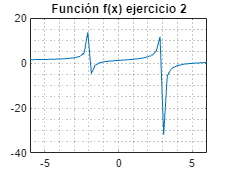


plot(x,y)
title("Función f(x) ejercicio 2")
grid minor

## 2. Iteraciones

Calcula el valor del método itativo siguiente:


$$x_k = \frac12 \left(x_{k-1}+\frac{2}{x_{k-1}}\right) \quad k \geq 1, x_0 = 3$$


Haciendo uso de las instrucciones: 

- Bucle "for"

- Bucle "while"

En todos los casos compara el resultado obtenido con el valor $\sqrt{2}$.

#### Ejercicio 3. Bucle for

Calcula los valores de las iteraciones, el error absoluto y relativo hasta k=10. Guarda los resultados de todas las iteraciones en vectores. Por último, presenta el resultado en una tabla en MATLAB.

format longG

xk = (1:10)'

xk =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


xk(1) = 3

xk =      3
     2
     3
     4
     5
     6
     7
     8
     9
    10



for i = 1:10
    xk(i+1) = (xk(i) + 2 / xk(i)) / 2 
end

xk =                          3
          1.83333333333333
                         3
                         4
                         5
                         6
                         7
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
                         4
                         5
                         6
                         7
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
                         5
                         6
                         7
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
                         6
                         7
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
                         7
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
          1.41421356237309
                         8
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
          1.41421356237309
          1.41421356237309
                         9
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
          1.41421356237309
          1.41421356237309
          1.41421356237309
                        10


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
          1.41421356237309
          1.41421356237309
          1.41421356237309
          1.41421356237309


xk =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311
          1.41421356237309
          1.41421356237309
          1.41421356237309
          1.41421356237309



Ea = abs(sqrt(2) - xk)

Ea =            1.5857864376269
         0.419119770960238
         0.047907649748117
      0.000784867521707922
      2.17674102520604e-07
      1.66533453693773e-14
      2.22044604925031e-16
      2.22044604925031e-16
      2.22044604925031e-16
      2.22044604925031e-16


Er = Ea / sqrt(2)

Er =           1.12132034355964
         0.296362432175337
        0.0338758240076035
      0.000554985146932751
      1.53918833981015e-07
      1.17756934401283e-14
      1.57009245868377e-16
      1.57009245868377e-16
      1.57009245868377e-16
      1.57009245868377e-16



table(xk,Ea,Er)

ans = 11×3 table
           xk                    Ea                      Er         
    ________________    ____________________    ____________________

                   3         1.5857864376269        1.12132034355964
    1.83333333333333       0.419119770960238       0.296362432175337
    1.46212121212121       0.047907649748117      0.0338758240076035
     1.4149984298948    0.000784867521707922    0.000554985146932751
     1.4142137800472    2.17674102520604e-07    1.53918833981015e-07
    1.41421356237311    1.66533453693773e-14    1.17756934401283e-14
    1.41421356237309    2.22044604925031e-16    1.57009245868377e-16
    1.41421356237309    2.22044604925031e-16    1.57009245868377e-16
    1.41421356237309    2.22044604925031e-16    1.57009245868377e-16
    1.41421356237309    2.22044604925031e-16    1.57009245868377e-16
    1.41421356237309    2.22044604925031e-16    1.57

#### Ejercicio 4. Bucle while

Calcula los 5 primeros valores de los iterados con un bulce while. Después calcula todas las iteraciones hasta que el error absoluto sea menor que 1.e-6. En ambos casos presenta los resultados en una tabla en MATLAB.

format longG

xk_a = 3

xk_a =      3



xk_b = xk_a

xk_b =      3


Ea_a = abs(sqrt(2) - xk_a(1))

Ea_a =            1.5857864376269


Er_a = Ea_a(1) / sqrt(2)

Er_a =           1.12132034355964



Ea_b = Ea_a

Ea_b =            1.5857864376269


Er_b = Er_a

Er_b =           1.12132034355964



idx = 1

idx =      1



%% 5 primeras iteraciones
while idx <= 5
    xk_a(end+1) = ( xk_a(end) + 2 / xk_a(end) )/2
    Ea_a(end+1) = abs(sqrt(2) - xk_a(end))
    Er_a(end+1) = Ea_a(end) / sqrt(2)
    idx = idx + 1
end

xk_a =                          3          1.83333333333333


Ea_a =            1.5857864376269         0.419119770960238


Er_a =           1.12132034355964         0.296362432175337


idx =      2


xk_a =                          3          1.83333333333333          1.46212121212121


Ea_a =            1.5857864376269         0.419119770960238         0.047907649748117


Er_a =           1.12132034355964         0.296362432175337        0.0338758240076035


idx =      3


xk_a =                          3          1.83333333333333          1.46212121212121           1.4149984298948


Ea_a =            1.5857864376269         0.419119770960238         0.047907649748117      0.000784867521707922


Er_a =           1.12132034355964         0.296362432175337        0.0338758240076035      0.000554985146932751


idx =      4


xk_a =                          3          1.83333333333333          1.46212121212121           1.4149984298948           1.4142137800472


Ea_a =            1.5857864376269         0.419119770960238         0.047907649748117      0.000784867521707922      2.17674102520604e-07


Er_a =           1.12132034355964         0.296362432175337        0.0338758240076035      0.000554985146932751      1.53918833981015e-07


idx =      5


xk_a =                          3          1.83333333333333          1.46212121212121           1.4149984298948           1.4142137800472          1.41421356237311


Ea_a =            1.5857864376269         0.419119770960238         0.047907649748117      0.000784867521707922      2.17674102520604e-07      1.66533453693773e-14


Er_a =           1.12132034355964         0.296362432175337        0.0338758240076035      0.000554985146932751      1.53918833981015e-07      1.17756934401283e-14


idx =      6



%%Hasta que el error sea de 10^-6
while Ea_b(end) >= 10^-6
   xk_b(end+1) = ( xk_b(end) + 2 / xk_b(end) )/2
   Ea_b(end+1) = abs(sqrt(2) - xk_b(end))
   Er_b(end+1) = Ea_b(end) / sqrt(2)
end

xk_b =                          3          1.83333333333333


Ea_b =            1.5857864376269         0.419119770960238


Er_b =           1.12132034355964         0.296362432175337


xk_b =                          3          1.83333333333333          1.46212121212121


Ea_b =            1.5857864376269         0.419119770960238         0.047907649748117


Er_b =           1.12132034355964         0.296362432175337        0.0338758240076035


xk_b =                          3          1.83333333333333          1.46212121212121           1.4149984298948


Ea_b =            1.5857864376269         0.419119770960238         0.047907649748117      0.000784867521707922


Er_b =           1.12132034355964         0.296362432175337        0.0338758240076035      0.000554985146932751


xk_b =                          3          1.83333333333333          1.46212121212121           1.4149984298948           1.4142137800472


Ea_b =            1.5857864376269         0.419119770960238         0.047907649748117      0.000784867521707922      2.17674102520604e-07


Er_b =           1.12132034355964         0.296362432175337        0.0338758240076035      0.000554985146932751      1.53918833981015e-07



xk_a = xk_a'

xk_a =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472
          1.41421356237311


Ea_a = Ea_a'

Ea_a =            1.5857864376269
         0.419119770960238
         0.047907649748117
      0.000784867521707922
      2.17674102520604e-07
      1.66533453693773e-14


Er_a = Er_a'

Er_a =           1.12132034355964
         0.296362432175337
        0.0338758240076035
      0.000554985146932751
      1.53918833981015e-07
      1.17756934401283e-14



xk_b = xk_b'

xk_b =                          3
          1.83333333333333
          1.46212121212121
           1.4149984298948
           1.4142137800472


Ea_b = Ea_b'

Ea_b =            1.5857864376269
         0.419119770960238
         0.047907649748117
      0.000784867521707922
      2.17674102520604e-07


Er_b = Er_b'

Er_b =           1.12132034355964
         0.296362432175337
        0.0338758240076035
      0.000554985146932751
      1.53918833981015e-07



table(xk_a, Ea_a, Er_a)

ans = 6×3 table
          xk_a                  Ea_a                    Er_a        
    ________________    ____________________    ____________________

                   3         1.5857864376269        1.12132034355964
    1.83333333333333       0.419119770960238       0.296362432175337
    1.46212121212121       0.047907649748117      0.0338758240076035
     1.4149984298948    0.000784867521707922    0.000554985146932751
     1.4142137800472    2.17674102520604e-07    1.53918833981015e-07
    1.41421356237311    1.66533453693773e-14    1.17756934401283e-14


table(xk_b, Ea_b, Er_b)

ans = 5×3 table
          xk_b                  Ea_b                    Er_b        
    ________________    ____________________    ____________________

                   3         1.5857864376269        1.12132034355964
    1.83333333333333       0.419119770960238       0.296362432175337
    1.46212121212121       0.047907649748117      0.0338758240076035
     1.4149984298948    0.000784867521707922    0.000554985146932751
     1.4142137800472    2.17674102520604e-07    1.53918833981015e-07


## 3. Funciones

#### Ejercicio 5. [Funciones anónimas](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

Evalua las funciones


$$f(x) = \sqrt{x^2 +1} -1, \quad g(x) = \frac{x^2}{\sqrt{x^2+1}+1}$$


para la sucesión de valores de $x_n = 8^{-n}, n \geq 1$. Aunque $f(x) = g(x)$, el ordenador da resultados diferentes. ¿Qué resultados son de fiar y cuáles no? ¿Por qué? Justifica la respuesta.

f = @(x) sqrt(x.^2 + 1) - 1

f = function_handle with value:
    @(x)sqrt(x.^2+1)-1


g = @(x) x.^2 ./ (sqrt(x.^2 + 1) + 1)

g = function_handle with value:
    @(x)x.^2./(sqrt(x.^2+1)+1)



%% En la solución empieza desde n = 0 pero el enunciado dice desde n = 1
ns = 1:30

ns =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


x = 8 .^ -ns

x =                      0.125                  0.015625               0.001953125            0.000244140625          3.0517578125e-05        3.814697265625e-06      4.76837158203125e-07      5.96046447753906e-08      7.45058059692383e-09      9.31322574615479e-10      1.16415321826935e-10      1.45519152283669e-11      1.81898940354586e-12      2.27373675443232e-13       2.8421709430404e-14       3.5527136788005e-15      4.44089209850063e-16      5.55111512312578e-17      6.93889390390723e-18      8.67361737988404e-19       1.0842021724855e-19      1.35525271560688e-20       1.6940658945086e-21      2.11758236813575e-22      2.64697796016969e-23      3.30872245021211e-24      4.13590306276514e-25      5.16987882845642e-26      6.46234853557053e-27      8.07793566946316e-28



fXs = f(x)

fXs =        0.00778221853731864      0.000122062862828676       1.9073468138231e-06      2.98023219436061e-08      4.65661287307739e-10      7.27595761418343e-12      1.13686837721616e-13      1.77635683940025e-15                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0


gXs = g(x)

gXs =        0.00778221853731871      0.000122062862828759      1.90734681382657e-06      2.98023219436061e-08      4.65661287199319e-10      7.27595761415696e-12       1.1368683772161e-13      1.77635683940025e-15      2.77555756156289e-17      4.33680868994202e-19       6.7762635780344e-21      1.05879118406788e-22      1.65436122510606e-24      2.58493941422821e-26      4.03896783473158e-28      6.31088724176809e-30      9.86076131526265e-32      1.54074395550979e-33      2.40741243048404e-35      3.76158192263132e-37      5.87747175411144e-39      9.18354961579912e-41      1.43492962746861e-42      2.24207754291971e-44      3.50324616081204e-46      5.47382212626882e-48      8.55284707229503e-50       1.3363823550461e-51      2.08809742975953e-53      3.26265223399926e-55



x = x'

x =                      0.125
                  0.015625
               0.001953125
            0.000244140625
          3.0517578125e-05
        3.814697265625e-06
      4.76837158203125e-07
      5.96046447753906e-08
      7.45058059692383e-09
      9.31322574615479e-10


fXs = fXs'

fXs =        0.00778221853731864
      0.000122062862828676
       1.9073468138231e-06
      2.98023219436061e-08
      4.65661287307739e-10
      7.27595761418343e-12
      1.13686837721616e-13
      1.77635683940025e-15
                         0
                         0


gXs = gXs'

gXs =        0.00778221853731871
      0.000122062862828759
      1.90734681382657e-06
      2.98023219436061e-08
      4.65661287199319e-10
      7.27595761415696e-12
       1.1368683772161e-13
      1.77635683940025e-15
      2.77555756156289e-17
      4.33680868994202e-19



table(x,fXs,gXs)

ans = 30×3 table
             x                      fXs                     gXs         
    ____________________    ____________________    ____________________

                   0.125     0.00778221853731864     0.00778221853731871
                0.015625    0.000122062862828676    0.000122062862828759
             0.001953125     1.9073468138231e-06    1.90734681382657e-06
          0.000244140625    2.98023219436061e-08    2.98023219436061e-08
        3.0517578125e-05    4.65661287307739e-10    4.65661287199319e-10
      3.814697265625e-06    7.27595761418343e-12    7.27595761415696e-12
    4.76837158203125e-07    1.13686837721616e-13     1.1368683772161e-13
    5.96046447753906e-08    1.77635683940025e-15    1.77635683940025e-15
    7.45058059692383e-09                       0    2.77555756156289e-17
    9.31322574615479e-10                       0    4.33680868994202e-19
    


%% Los resultados de la función g(x) son más precisos ya que a partir de la iteración número 9
%% el resultado de f(x) es 0 (probablemente por errores de redondeamiento internos de MatLab?),
%% mientras que los de g(x) son decimales minúsculos.

Haz un juego de pruebas para diferentes $x_n$, por ejemplo toma $5^{-n}, 7^{-n}, 9^{-n} ...$

f = @(x) sqrt(x.^2 + 1) - 1

f = function_handle with value:
    @(x)sqrt(x.^2+1)-1


g = @(x) x.^2 ./ (sqrt(x.^2 + 1) + 1)

g = function_handle with value:
    @(x)x.^2./(sqrt(x.^2+1)+1)



%% En la solución empieza desde n = 0 pero el enunciado dice desde n = 1
ns = 1:30

ns =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


x_a = 5 .^ -ns

x_a =                        0.2                      0.04                     0.008                    0.0016                   0.00032                   6.4e-05                  1.28e-05                  2.56e-06                  5.12e-07                 1.024e-07                 2.048e-08                 4.096e-09                 8.192e-10                1.6384e-10                3.2768e-11                6.5536e-12               1.31072e-12               2.62144e-13               5.24288e-14              1.048576e-14              2.097152e-15              4.194304e-16              8.388608e-17             1.6777216e-17             3.3554432e-18             6.7108864e-19            1.34217728e-19            2.68435456e-20            5.36870912e-21           1.073741824e-21


x_b = 7 .^ -ns

x_b =          0.142857142857143        0.0204081632653061       0.00291545189504373       0.00041649312786339      5.94990182661986e-05      8.49985975231409e-06      1.21426567890201e-06       1.7346652555743e-07        2.478093222249e-08      3.54013317464144e-09      5.05733310663062e-10      7.22476158090089e-11      1.03210879727156e-11      1.47444113895937e-12      2.10634448422766e-13      3.00906354889666e-14      4.29866221270952e-15      6.14094601815646e-16      8.77278002593779e-17      1.25325428941968e-17      1.79036327059955e-18      2.55766181514221e-19      3.65380259306031e-20      5.21971799008615e-21      7.45673998583736e-22      1.06524856940534e-22      1.52178367057905e-23      2.17397667225579e-24      3.10568096036541e-25      4.43668708623631e-26


x_c = 9 .^ -ns

x_c =          0.111111111111111        0.0123456790123457       0.00137174211248285      0.000152415790275873      1.69350878084303e-05      1.88167642315892e-06      2.09075158128769e-07      2.32305731254188e-08       2.5811747917132e-09      2.86797199079244e-10      3.18663554532493e-11      3.54070616147215e-12      3.93411795719128e-13      4.37124217465698e-14      4.85693574961886e-15      5.39659527735429e-16       5.9962169748381e-17      6.66246330537567e-18      7.40273700597296e-19      8.22526333996996e-20      9.13918148885551e-21      1.01546460987283e-21      1.12829401096982e-22      1.25366001218868e-23      1.39295556909854e-24      1.54772841010949e-25      1.71969823345499e-26      1.91077581494998e-27      2.12308423883332e-28      2.35898248759257e-29



fXs_a = f(x_a)

fXs_a =          0.019803902718557      0.000799680255744395      3.19994880164653e-05      1.27999918086985e-06      5.11999986851919e-08       2.0479999918166e-09      8.19200263180164e-11      3.27671223487869e-12      1.31006316905768e-13      5.10702591327572e-15      2.22044604925031e-16                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0


gXs_a = g(x_a)

gXs_a =          0.019803902718557      0.000799680255744286      3.19994880163833e-05      1.27999918080105e-06      5.11999986892801e-08      2.04799999790285e-09      8.19199999966445e-11      3.27679999999463e-12      1.31071999999991e-13      5.24287999999999e-15              2.097152e-16              8.388608e-18             3.3554432e-19            1.34217728e-20            5.36870912e-22           2.147483648e-23           8.589934592e-25          3.4359738368e-26         1.37438953472e-27         5.49755813888e-29        2.199023255552e-30        8.796093022208e-32       3.5184372088832e-33      1.40737488355328e-34      5.62949953421312e-36      2.25179981368525e-37      9.00719925474099e-39       3.6028797018964e-40      1.44115188075856e-41      5.76460752303424e-43


fXs_b = f(x_b)

fXs_b =         0.0101525445522108      0.000208224885130281      4.24992084524511e-06      8.67332590193115e-08      1.77006653778733e-09      3.61237706414386e-11      7.37188088351104e-13      1.50990331349021e-14      2.22044604925031e-16                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0


gXs_b = g(x_b)

gXs_b =         0.0101525445522107      0.000208224885130301      4.24992084524345e-06      8.67332590173861e-08      1.77006658575415e-09       3.6123807903852e-11      7.37220569479411e-13      1.50453177444832e-14      3.07047300907823e-16      6.26627144709842e-18      1.27883090757111e-19      2.60985899504308e-21      5.32624284702668e-23      1.08698833612789e-24      2.21834354311815e-26      4.52723172064929e-28      9.23924840948835e-30      1.88556089989558e-31      3.84808346917466e-33       7.8532315697442e-35      1.60270032035596e-36      3.27081698031828e-38      6.67513669452711e-40      1.36227279480145e-41      2.78014856081929e-43      5.67377257310059e-45      1.15791277002053e-46      2.36308728575618e-48      4.82262711378812e-50        9.842096150588e-52


fXs_c = f(x_c)

fXs_c =        0.00615390423749074      7.62049915374874e-05      9.40837769025649e-07      1.16152865103913e-08      1.43398626306634e-10      1.77036163506727e-12      2.17603712826531e-14      2.22044604925031e-16                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0


gXs_c = g(x_c)

gXs_c =        0.00615390423749074      7.62049915375687e-05      9.40837768991607e-07      1.16152864952519e-08       1.4339859952934e-10      1.77035308073451e-12      2.18562108732846e-14      2.69829763867715e-16      3.33123165268783e-18      4.11263166998498e-20      5.07732304936417e-22      6.26830006094342e-24      7.73864205054744e-26      9.55387907474992e-28      1.17949124379629e-29      1.45616202937813e-31      1.79773090046683e-33      2.21942086477386e-35      2.74002575898008e-37      3.38274785059269e-39      4.17623191431196e-41      5.15584186952094e-43      6.36523687595178e-45      7.85831713080466e-47      9.70162608741317e-49      1.19773161573002e-50       1.4786810070741e-52      1.82553210749889e-54      2.25374334259122e-56      2.78239918838422e-58



x_a = x_a'

x_a =                        0.2
                      0.04
                     0.008
                    0.0016
                   0.00032
                   6.4e-05
                  1.28e-05
                  2.56e-06
                  5.12e-07
                 1.024e-07


x_b = x_b'

x_b =          0.142857142857143
        0.0204081632653061
       0.00291545189504373
       0.00041649312786339
      5.94990182661986e-05
      8.49985975231409e-06
      1.21426567890201e-06
       1.7346652555743e-07
        2.478093222249e-08
      3.54013317464144e-09


x_c = x_c'

x_c =          0.111111111111111
        0.0123456790123457
       0.00137174211248285
      0.000152415790275873
      1.69350878084303e-05
      1.88167642315892e-06
      2.09075158128769e-07
      2.32305731254188e-08
       2.5811747917132e-09
      2.86797199079244e-10


fXs_a = fXs_a'

fXs_a =          0.019803902718557
      0.000799680255744395
      3.19994880164653e-05
      1.27999918086985e-06
      5.11999986851919e-08
       2.0479999918166e-09
      8.19200263180164e-11
      3.27671223487869e-12
      1.31006316905768e-13
      5.10702591327572e-15


fXs_b = fXs_b'

fXs_b =         0.0101525445522108
      0.000208224885130281
      4.24992084524511e-06
      8.67332590193115e-08
      1.77006653778733e-09
      3.61237706414386e-11
      7.37188088351104e-13
      1.50990331349021e-14
      2.22044604925031e-16
                         0


fXs_c = fXs_c'

fXs_c =        0.00615390423749074
      7.62049915374874e-05
      9.40837769025649e-07
      1.16152865103913e-08
      1.43398626306634e-10
      1.77036163506727e-12
      2.17603712826531e-14
      2.22044604925031e-16
                         0
                         0


gXs_a = gXs_a'

gXs_a =          0.019803902718557
      0.000799680255744286
      3.19994880163833e-05
      1.27999918080105e-06
      5.11999986892801e-08
      2.04799999790285e-09
      8.19199999966445e-11
      3.27679999999463e-12
      1.31071999999991e-13
      5.24287999999999e-15


gXs_b = gXs_b'

gXs_b =         0.0101525445522107
      0.000208224885130301
      4.24992084524345e-06
      8.67332590173861e-08
      1.77006658575415e-09
       3.6123807903852e-11
      7.37220569479411e-13
      1.50453177444832e-14
      3.07047300907823e-16
      6.26627144709842e-18


gXs_c = gXs_c'

gXs_c =        0.00615390423749074
      7.62049915375687e-05
      9.40837768991607e-07
      1.16152864952519e-08
       1.4339859952934e-10
      1.77035308073451e-12
      2.18562108732846e-14
      2.69829763867715e-16
      3.33123165268783e-18
      4.11263166998498e-20



table(x_a,fXs_a,gXs_a)

ans = 30×3 table
       x_a               fXs_a                   gXs_a        
    __________    ____________________    ____________________

           0.2       0.019803902718557       0.019803902718557
          0.04    0.000799680255744395    0.000799680255744286
         0.008    3.19994880164653e-05    3.19994880163833e-05
        0.0016    1.27999918086985e-06    1.27999918080105e-06
       0.00032    5.11999986851919e-08    5.11999986892801e-08
       6.4e-05     2.0479999918166e-09    2.04799999790285e-09
      1.28e-05    8.19200263180164e-11    8.19199999966445e-11
      2.56e-06    3.27671223487869e-12    3.27679999999463e-12
      5.12e-07    1.31006316905768e-13    1.31071999999991e-13
     1.024e-07    5.10702591327572e-15    5.24287999999999e-15
     2.048e-08    2.22044604925031e-16            2.097152e-16
     4.096e-09                       0            8.388608e-1

table(x_b,fXs_b,gXs_b)

ans = 30×3 table
            x_b                    fXs_b                   gXs_b        
    ____________________    ____________________    ____________________

       0.142857142857143      0.0101525445522108      0.0101525445522107
      0.0204081632653061    0.000208224885130281    0.000208224885130301
     0.00291545189504373    4.24992084524511e-06    4.24992084524345e-06
     0.00041649312786339    8.67332590193115e-08    8.67332590173861e-08
    5.94990182661986e-05    1.77006653778733e-09    1.77006658575415e-09
    8.49985975231409e-06    3.61237706414386e-11     3.6123807903852e-11
    1.21426567890201e-06    7.37188088351104e-13    7.37220569479411e-13
     1.7346652555743e-07    1.50990331349021e-14    1.50453177444832e-14
      2.478093222249e-08    2.22044604925031e-16    3.07047300907823e-16
    3.54013317464144e-09                       0    6.26627144709842e-18
    

table(x_c,fXs_c,gXs_c)

ans = 30×3 table
            x_c                    fXs_c                   gXs_c        
    ____________________    ____________________    ____________________

       0.111111111111111     0.00615390423749074     0.00615390423749074
      0.0123456790123457    7.62049915374874e-05    7.62049915375687e-05
     0.00137174211248285    9.40837769025649e-07    9.40837768991607e-07
    0.000152415790275873    1.16152865103913e-08    1.16152864952519e-08
    1.69350878084303e-05    1.43398626306634e-10     1.4339859952934e-10
    1.88167642315892e-06    1.77036163506727e-12    1.77035308073451e-12
    2.09075158128769e-07    2.17603712826531e-14    2.18562108732846e-14
    2.32305731254188e-08    2.22044604925031e-16    2.69829763867715e-16
     2.5811747917132e-09                       0    3.33123165268783e-18
    2.86797199079244e-10                       0    4.11263166998498e-20
    


%% Se observa que cuanto más grande es la base del exponente, antes ocurre este
%% redondeamiento a 0 en f(x), mientras que g(x) sigue dando resultados

#### Ejercicio 6. [Funciones en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

- Escribe una funcion que devuelva el error relativo de los datos $x, \tilde{x}$.

- Escribe una funcion que devuelva los decimales exactos y las cifras significativas de los datos $x, \tilde x$.

Haz un juego de pruebas

x = 1/3; xa = 0.3333; 

erA = relErr(x,xa)

erA =        9.9999999999989e-05


x = pi; xa = 3.1416; 
erB = relErr(x,xa)

erB =       2.33843499679617e-06


function er = relErr(xreal,xmedida)
    er = (abs(xreal- xmedida)) / xreal;
end

%% TODO funcion de xifres significativas y decimales exactos...

## Para hacer ....

## 4. Trabajo autónomo. Ejercicios de la lista: del 1 al 10.

% Funciones internas


`Documento preparado por I. Parada, 14 de febrero de 2023`